C_OP = readmatrix("cost_OP_plot.csv");
C_Move = readmatrix("cost_Move_plot.csv");
C_Manipulation = readmatrix("cost_Manipulation_plot.csv");
C_Obst = readmatrix("cost_Obst_plot.csv");
params = readtable("cost_function_params.csv");

% Import Params
[X,Y] = meshgrid(params.x_range0:params.x_step:(params.x_range1-params.x_step), ...
    params.y_range0:params.y_step:params.y_range1-params.y_step);
start = [params.start_x, params.start_y, params.C_start];
C_opt = cell2mat({params.C_opt_x, params.C_opt_y, params.C_opt});


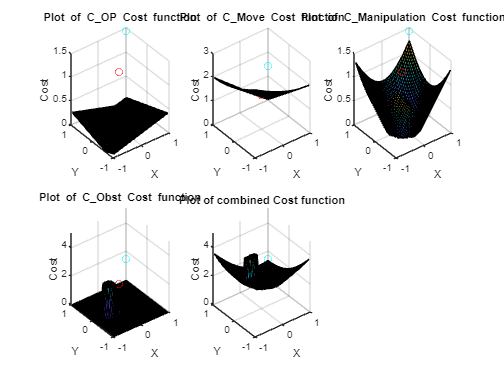

figure();

% Plot C_OP
subplot(2,3,1);
surf(X, Y, C_OP)
title("Plot of C\_OP Cost function");
xlabel("X");
ylabel("Y");
zlabel("Cost");

hold on
scatter3(C_opt(1), C_opt(2), C_opt(3), 'red');
scatter3(start(1), start(2), start(3), 'cyan')
hold off

% Plot C_Move
subplot(2,3,2);
surf(X, Y, C_Move)
title("Plot of C\_Move Cost function");
xlabel("X");
ylabel("Y");
zlabel("Cost");

hold on
scatter3(C_opt(1), C_opt(2), C_opt(3), 'red');
scatter3(start(1), start(2), start(3), 'cyan')
hold off

% Plot C_Maniplation
subplot(2,3,3);
surf(X, Y, C_Manipulation)
title("Plot of C\_Manipulation Cost function");
xlabel("X");
ylabel("Y");
zlabel("Cost");

hold on
scatter3(C_opt(1), C_opt(2), C_opt(3), 'red');
scatter3(start(1), start(2), start(3), 'cyan')
hold off

% Plot C_Obst
subplot(2,3,4);
surf(X, Y, C_Obst)
title("Plot of C\_Obst Cost function");
xlabel("X");
ylabel("Y");
zlabel("Cost");
zlim([0, 5])

hold on
scatter3(C_opt(1), C_opt(2), C_opt(3), 'red');
scatter3(start(1), start(2), start(3), 'cyan')
hold off

% Plot Total Cost
subplot(2,3,5)
surf(X, Y, C_OP + C_Move + C_Manipulation + C_Obst )
title("Plot of combined Cost function");
xlabel("X");
ylabel("Y");
zlabel("Cost");
zlim([0, 5]);

hold on
scatter3(C_opt(1), C_opt(2), C_opt(3), 'red');
scatter3(start(1), start(2), start(3), 'cyan')
hold off